# 数据类型与文件读写

## 数值类型(numeric)

n = 3;
class(n)	% 得到 double

ans = 'double'


n = int8(3);
class(n)	% 得到 int8

ans = 'int8'

## 字符串类型(char)

s1 = 'h';
uint16(s1)	% 得到 104

ans = uint16
104


% 字符矩阵
str1 = 'hello';
str2 = 'world';

str3 = [str1 str2];
str3

str3 = 'helloworld'

size(str3)		% 得到 [1 10]

ans =      1    10



str4 = [str1; str2];
str4

str4 = 2×5 char 数组
    'hello'
    'world'


size(str4)		% 得到 [2 5]

ans =      2     5



% 字符串匹配
str = 'aardvark';
'a' == str				% 得到 [1 1 0 0 0 1 0 0]

ans = 1×8 logical 数组
   1   1   0   0   0   1   0   0


str(str == 'a') = 'Z'	% 得到 'ZZrdvZrk'

str = 'ZZrdvZrk'

## 结构体

% 在MATLAB中,结构体是一个存储{键: 值}的数据结构,类似于Python语言中的字典
student.name = 'John Doe';
student.id = 'jdo2@sfu.ca';
student.number = 301073268;
student.grade = [100, 75, 73; ...
                 95, 91, 85.5; ...
                 100, 98, 72];
student

student = 包含以下字段的 struct :
      name: 'John Doe'
        id: 'jdo2@sfu.ca'
    number: 301073268
     grade: [3×3 double]



% 对结构体列表使用下标表达式可以扩充或缩减结构体列表
student(2).name = 'Ann Lane';
student(2).id = 'aln4@sfu.ca';
student(2).number = 301078853;
student(2).grade = [95 100 90; 95 82 97; 100 85 100];
student

student = 包含以下字段的 1×2 struct 数组:
    name
    id
    number
    grade



student(1) = []		% 删除student列表第一项

student = 包含以下字段的 struct :
      name: 'Ann Lane'
        id: 'aln4@sfu.ca'
    number: 301078853
     grade: [3×3 double]



% 获取结构体的所有字段名
fieldnames(student)

ans = 4×1 cell 数组
    {'name'  }
    {'id'    }
    {'number'}
    {'grade' }


## 元胞数组(cell)

% 使用{}像定义矩阵一样定义元胞数组
A = { [1 4 3; 0 5 8; 7 2 9]		'Anne Smith' ;...
3+7i		-pi:pi:pi}

A = 2×2 cell 数组
    {3×3 double        }    {'Anne Smith'      }
    {[3.0000 + 7.0000i]}    {[-3.1416 0 3.1416]}



A(1,1)={[1 4 3; 0 5 8; 7 2 9]};
A(1,2)={'Anne Smith'};
A(2,1)={3+7i};
A(2,2)={-pi:pi:pi};
A

A = 2×2 cell 数组
    {3×3 double        }    {'Anne Smith'      }
    {[3.0000 + 7.0000i]}    {[-3.1416 0 3.1416]}



A{1,1}=[1 4 3; 0 5 8; 7 2 9];
A{1,2}='Anne Smith';
A{2,1}=3+7i;
A{2,2}=-pi:pi:pi;
A

A = 2×2 cell 数组
    {3×3 double        }    {'Anne Smith'      }
    {[3.0000 + 7.0000i]}    {[-3.1416 0 3.1416]}



% 两种方式访问元胞数组中的数据,分别是: 单元索引()和内容索引{}
A(1,1) % 子元数组           cell

ans = 1×1 cell 数组
    {3×3 double}


ans =      1     4     3
     0     5     8
     7     2     9


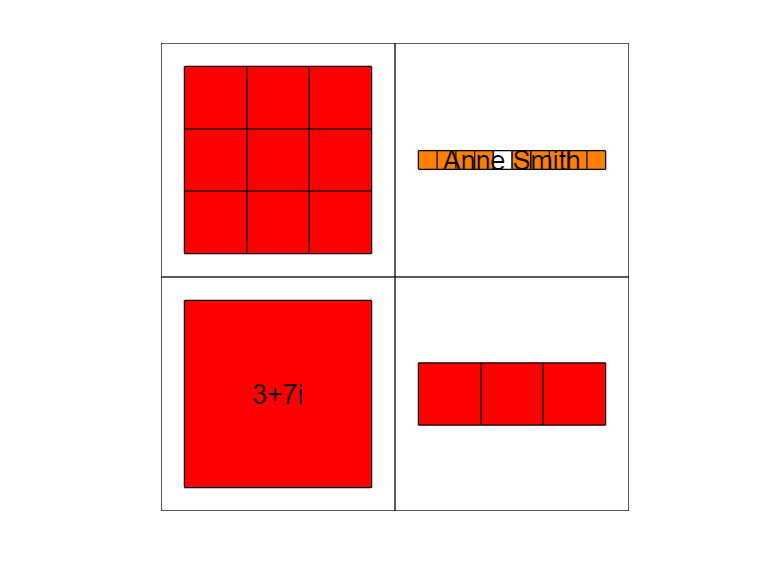

A{1,1} % 元数组对应的内容   矩阵

## 文件读写